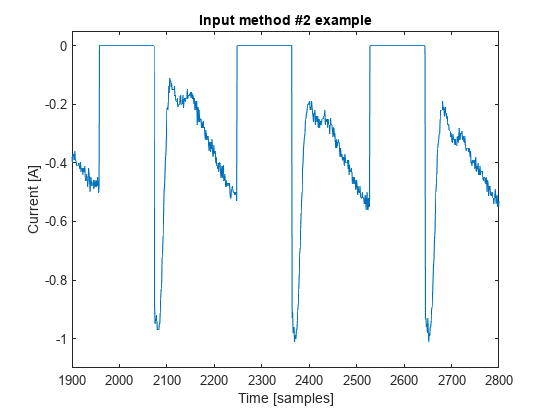

clear
load('data.mat')

Te=data.parownik;
Tc=data.SondaSterujca;
compressor=data.compressor;

[Te,~]=GetRidOfNans(Te);
[Tc,~]=GetRidOfNans(Tc);
[compressor,~]=GetRidOfNans(compressor);

coeff=1;
out=(Te-Tc).*compressor.*coeff;
figure
plot(out);
title('Input method #2 example')
xlabel('Time [samples]')
ylabel('Current [A]')
xlim([1900,2800])
ylim([-1.1,0.05])

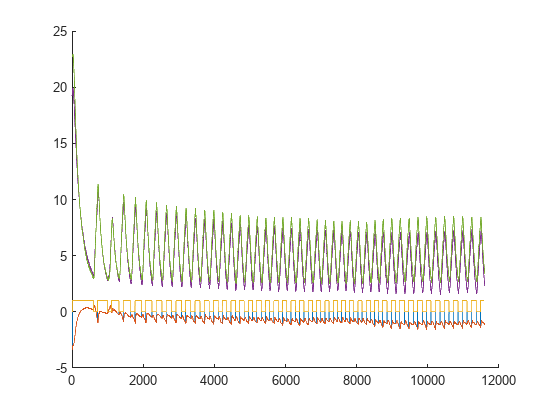

figure
hold on
plot(out)
plot((Te-Tc))
plot(compressor)
plot(Te)
plot(Tc);hold off

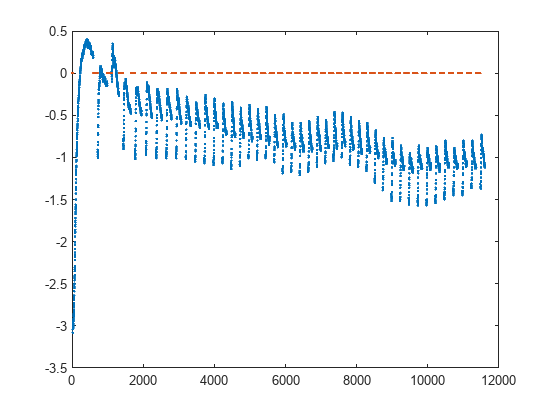



count=0;
count2=0;
for i=1:length(out)
    
    if compressor(i)==1
        count=count+1;
        outPlot(count)=out(i);
        outPlotIndex(count)=i;
    else
        count2=count2+1;
        Index2(count2)=i;
    end
end
figure
plot(outPlotIndex,outPlot,'.');hold on
v=length(Index2);
plot(Index2,zeros(1,v),'.');hold off